load UStemps.mat
ustemp = readtable('UStemps.txt')

ustemp = 56×4 table
            City             JanTemp    Lat     Long 
    _____________________    _______    ____    _____

    {'Mobile, AL'       }      44       31.2     88.5
    {'Montgomery, AL'   }      38       32.9     86.8
    {'Phoenix, AZ'      }      35       33.6    112.5
    {'Little Rock, AR'  }      31       35.4     92.8
    {'Los Angeles, CA'  }      47       34.3    118.7
    {'San Francisco, CA'}      42       38.4      123
    {'Denver, CO'       }      15       40.7    105.3
    {'New Haven, CT'    }      22       41.7     73.4
    {'Wilmington, DE'   }      26       40.5     76.3
    {'Washington, DC'   }      30       39.7     77.5
    {'Jacksonville, FL' }      45         31     82.3
    {'Key West, FL'     }      65         25       82
    {'Miami, FL'        }      58       26.3     80.7
    {'Atlanta, GA'      }      37

UStemps adathalmaz, a következő változókat tartalmazza:

- **City**: A város neve és állama

- **JanTemp**: Janúári középhőmérséklet Fahrenheit-ben (°F) megadva

- **Lat**: szélességi fok (é-d)

- **Long**: hosszúsági fok (k-ny)

Első lépésként adjuk meg a januári középhőmérsékleteket Celsius-ban (°C), ha *32°F=0°C* és *212°F=100°C*.

tempc = (JanTemp -32)/1.8

tempc =     6.6667
    3.3333
    1.6667
   -0.5556
    8.3333
    5.5556
   -9.4444
   -5.5556
   -3.3333
   -1.1111


Számoljuk ki a **szélességi fok felső-kvartilisét**, majd ezek után **dolgozzunk csak azokkal a városokkal**, amelyek **szélességi foka kisebb mint** az előbb kiszámított **felső-kvartilis**!

Felső kvartilis:

upperQuan = quantile(Lat,0.75)

upperQuan = 42.6500

Városok, amelyek szélességi foka kisebb mint az előbb kiszámított felső-kvartilis!

smallerQuanCities = tempc(upperQuan>Lat,:)

smallerQuanCities =     6.6667
    3.3333
    1.6667
   -0.5556
    8.3333
    5.5556
   -9.4444
   -5.5556
   -3.3333
   -1.1111


Mi lesz ezen városok átlaghőmérsékletének az átlaga, korrigált szórása (sima szórás).

atlag = mean(smallerQuanCities)

atlag = -0.9524

szoras = std(smallerQuanCities)

szoras = 6.7634

Mi lesz azon városok aránya, ahol a középhőmérséklet fagyáspont (0°C) alatt van?

fagypontAlattArany = sum(smallerQuanCities<0)...
/length(smallerQuanCities)

fagypontAlattArany = 0.6429

Melyik városban volt a legmelegebb?

m = max(smallerQuanCities);
ind = find(smallerQuanCities == m);
ustemp(ind, "City")

ans = table
          City      
    ________________

    {'Key West, FL'}



% vagy

TrueFalseList = (smallerQuanCities == m);
ustemp.City(TrueFalseList,:)

ans = 1×1 cell array
    {'Key West, FL'}


Készítsen egy [Matlab](https://elearning.unideb.hu/mod/quiz/view.php?id=386146) függvényt, amely egy n-elemű **x** mintavektor és **t** valós szám esetén esetén visszaadja az alábbi képlet alapján definiált *empirikus eloszlásfüggvény *értékét a **t** helyen:

A függvény neve legyen **fun**, a kimenőváltozó legyen **F**. 

A változók definiálásánál használjon pontosvesszőt!

pkg load statistics

Unrecognized function or variable 'pkg'.

function F = fun(x, t)
    % ECDF függvény meghívása az empirikus eloszlásfüggvény létrehozásához
    [f, x_sorted] = ecdf(x);  % f = ecdf értékei, x_sorted = rendezett mintaváltozó
    
    % Az empirikus eloszlásfüggvény értékének meghatározása
    if t <= x_sorted(1)
        F = 0;  % Ha t kisebb vagy egyenlő az első elemnél
    elseif t > x_sorted(end)
        F = 1;  % Ha t nagyobb, mint a legnagyobb elem
    else
        % Az ECDF értéke t helyén
        index = find(x_sorted <= t, 1, 'last');
        F = f(index);
    end
end

% Mintavektor
x = [3, 6, 1, 7, 8];
t = 4;

% Az empirikus eloszlásfüggvény számítása a t = 4 értékre
disp(fun(x, t));  % A várt eredmény: 0.4

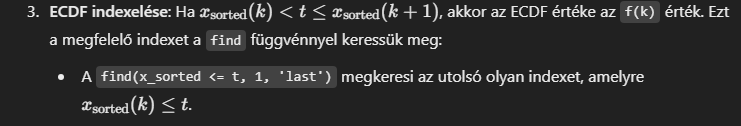

Készítsen egy [Matlab](https://elearning.unideb.hu/mod/quiz/view.php?id=386146) függvényt, amely egy n-elemű **x** mintavektor és **q** (0<q<1) szám esetén visszaadja az alábbi képlet alapján definiált *q-kvantilist*:

function Q = fun2(x, q)
    x_sorted = sort(x); % Rendezés
    n = length(x_sorted); % Minta elemszáma
    h = n*q+1/2; % A h index kiszámítása
    
    % Alsó egészrész
    h_floor = floor(h);
    
    % Q kiszámítása a megadott képlet szerint
    Q = x_sorted(h_floor) + (h - h_floor) * (x_sorted(h_floor + 1) - x_sorted(h_floor));
end

disp(fun2([9 2 4 7.2 11],0.3)) %4

ahol [.] az alsó-egészrész függvény, x∗x∗ a rendezett minta eleme.

A függvény neve legyen **fun**, a kimenőváltozó legyen **Q**.

Egy adott vektor a **sort(.)** paranccsal rendezhető növekvő sorrendbe.

Készítsen egy [Matlab](https://elearning.unideb.hu/mod/quiz/view.php?id=386146) függvényt, amely egy n-elemű **x** mintavektor esetén visszaadja az alábbi képlet alapján definiált *korrigált empirikus szórásnégyzetet*:

A függvény neve legyen **fun**, a kimenőváltozó legyen **s**. 

Az **s** meghatározásához használjon vektorműveleteket!

A  var, std, for, while, stb. parancsok tiltottak! 

function s = fun3(x)
    % Korrigált empirikus szórásnégyzet számítása
    % Bemenet:
    % x - n elemű minta vektora
    % Kimenet:
    % s - korrigált empirikus szórásnégyzet

    n = length(x);  % A minta elemszáma
    mean_x = mean(x);  % A minta átlaga (mean() parancs használható itt, nem tilos)
    
    % A négyzetek összegzése és normalizálás
    s = sum((x - mean_x).^2) / (n - 1);
end

disp(fun3([9 2 4 7.2 11])); %13.348